kf = 0.5

kf = 0.5000

h =1

h = 1

R =1

R = 1

C =1

C = 1

J= 1

J = 1

B =1

B = 1

km =1

km = 1

kw =1

kw = 1

La =1

La = 1

Ra=1

Ra = 1

syms V h w ia 
hp = (kf*w-h/R)/C

$$hp = \frac{w}{2}-h$$

wp=(km*ia-B*w)/J

$$wp = \mathrm{ia}-w$$

iap=(-kw*w-Ra*ia+V)/La

$$iap = V-\mathrm{ia}-w$$

x = [h w ia]

$$x = \left(\begin{array}{ccc} h & w & \mathrm{ia} \end{array}\right)$$

y = h 

$$y = h$$

A = jacobian ([hp; wp; iap], x)

$$A = \left(\begin{array}{ccc} -1 & \frac{1}{2} & 0\\ 0 & -1 & 1\\ 0 & -1 & -1 \end{array}\right)$$

B = jacobian ([hp; wp; iap], V)

$$B = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

C = jacobian (y, x)

$$C = \left(\begin{array}{ccc} 1 & 0 & 0 \end{array}\right)$$

D = jacobian (y, V)

$$D = 0$$


A = double(A)

A =    -1.0000    0.5000         0
         0   -1.0000    1.0000
         0   -1.0000   -1.0000


B = double(B)

B =      0
     0
     1


C = double(C)

C =      1     0     0


D = double(D)

D = 0


ee=ss(A,B,C,D)

ee =
 
  A = 
        x1   x2   x3
   x1   -1  0.5    0
   x2    0   -1    1
   x3    0   -1   -1
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



ft=tf(ee)

ft =
 
           0.5
  ---------------------
  s^3 + 3 s^2 + 4 s + 2
 
Continuous-time transfer function.



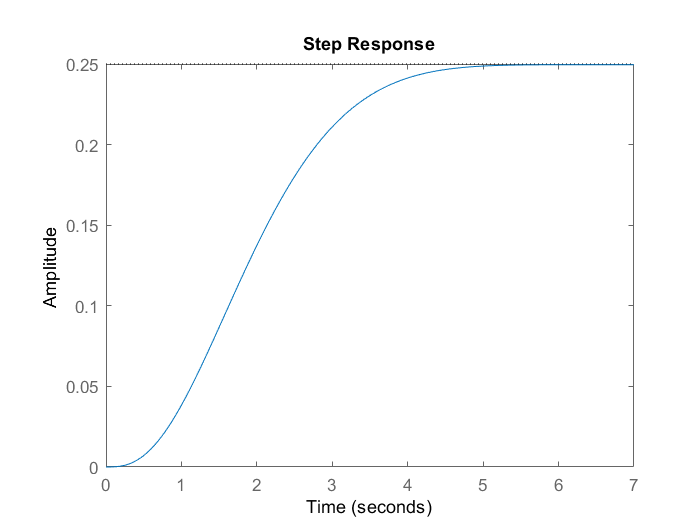

step(ft)

roots([1 3 4 2])

ans =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i
  -1.0000 + 0.0000i


syms s z Wn 
%polinomio deseado orden 4

y= (s^2+2*z*Wn*s+Wn^2)

$$y = {\mathrm{Wn}}^{2}+2\,z\,\mathrm{Wn}\,s+s^{2}$$

x= (s+10*z*Wn)^2

$$x = {\left(s+10\,\mathrm{Wn}\,z\right)}^{2}$$

collect(y*x,s)

$$ans = s^{4}+\left(22\,\mathrm{Wn}\,z\right)\,s^{3}+\left(140\,{\mathrm{Wn}}^{2}\,z^{2}+{\mathrm{Wn}}^{2}\right)\,s^{2}+\left(200\,{\mathrm{Wn}}^{3}\,z^{3}+20\,{\mathrm{Wn}}^{3}\,z\right)\,s+100\,{\mathrm{Wn}}^{4}\,z^{2}$$


syms kp ki kd1 kd2
% condiciones de diseño
z=0.7

z = 0.7000

Wn=1.47

Wn = 1.4700


%igulacion entre polinomos
%S^3
kd2=vpa(solve(22*Wn*z==3+0.5*kd2,kd2)) % lo que este acompañado de s^3 de escribe al otro lado del == 

$$kd2 = 39.276$$

%S^2
kd1=vpa(solve(140*Wn^2*z^2+Wn^2==4+0.5*kd1,kd1))  % lo que este acompañado de s^2 de escribe al otro lado del == 

$$kd1 = 292.79727999999988696799846366048$$

%S
kp=vpa(solve(200*Wn^3*z^3+20*Wn^3*z==2+0.5*kp,kp)) % lo que este acompañado de s de escribe al otro lado del == 

$$kp = 520.76159959999984039313858374953$$

%independiente
ki=vpa(solve(100*Wn^4*z^2==0.5*ki,ki)) % lo que este acompañado se escribe al otro lado del ==

$$ki = 457.60990337999993471385096199811$$


kd2=double(kd2)

kd2 = 39.2760

kd1=double(kd1)

kd1 = 292.7973

kp=double(kp)

kp = 520.7616

ki=double(ki)

ki = 457.6099


tm=0.05

tm = 0.0500

%calculo matched
PID=tf([kd2 kd1 kp ki],[1 0])

PID =
 
  39.28 s^3 + 292.8 s^2 + 520.8 s + 457.6
  ---------------------------------------
                     s
 
Continuous-time transfer function.



control=c2d(PID,tm, 'matched')

control =
 
  1.885e04 z^3 - 5.016e04 z^2 + 4.432e04 z - 1.299e04
  ---------------------------------------------------
                         z - 1
 
Sample time: 0.05 seconds
Discrete-time transfer function.



mu=control.Numerator{1}

mu = 	1.0e+04 *

    1.8852   -5.0159    4.4315   -1.2986


me=control.Denominator{1}

me =      0     0     1    -1
